clc
clear

load cog_Bike.mat 
load inertia_Bike.mat

mf = 2.02

mf = 2.0200

mb = 94;

hb = -cog_Bike(3)% reference frames have been changed from convention in Schwab

hb = 0.8612

hf= 0.9

hf = 0.9000

Ib = inertia_Bike(1,1)% Ixx!

Ib = 9.4597

Ip = 0.0088

Ip = 0.0088

Ir = 0.0224

Ir = 0.0224

w = 469

w = 469

L = 0.000119

L = 1.1900e-04

R = 0.61

R = 0.6100

Bm = 0.003

Bm = 0.0030

Km = 0.0259

Km = 0.0259

Ke = 0.0027

Ke = 0.0027

g = 9.81

g = 9.8100

A =[ 0 1 0 0;
    g*(mb*hb+mf*hf)/(mb*hb^2+mf*hf^2+Ib + Ir) 0 Ip*w/(mb*hb^2+mf*hf^2+Ib + Ir) 0;
    0 -Ip*w/Ir -Bm/Ir 65*Km/Ir;
    0 0 -Ke/L -R/L];
B = [0;0;0;1/L];
C = [1 0 0 0];
D = 0;
system= ss(A,B,C,D) % uncompensated systeemtem (no controller)


system =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2    10.05        0  0.05106        0
   x3        0   -184.3  -0.1339    75.16
   x4        0        0   -22.69    -5126
 
  B = 
         u1
   x1     0
   x2     0
   x3     0
   x4  8403
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



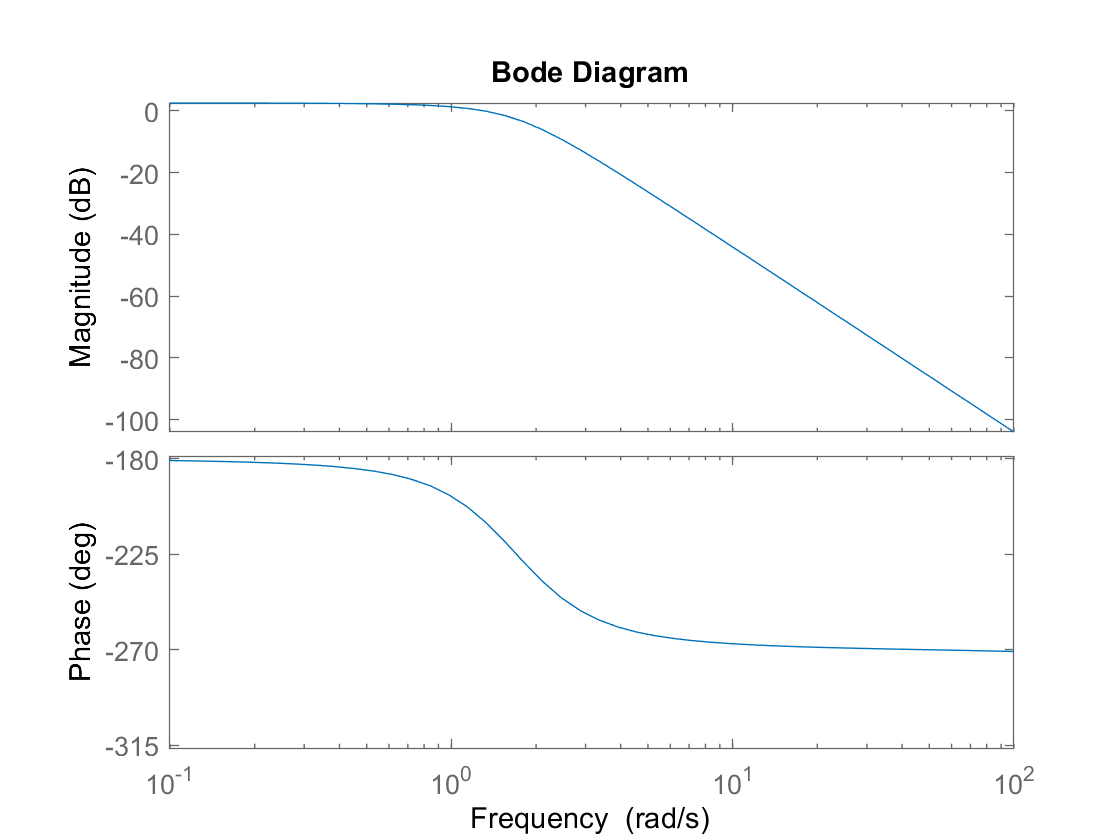


bode(system)

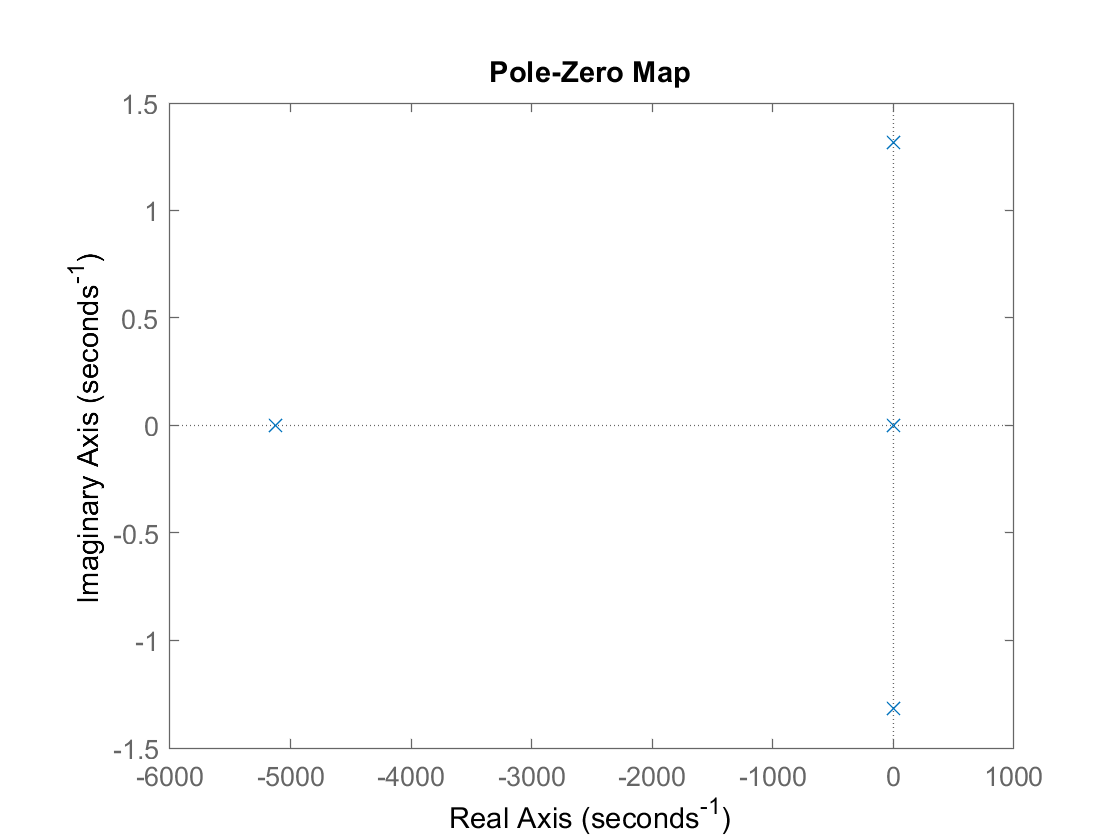

pzmap(system)

[num,den]=ss2tf(A,B,C,D)

num = 	1.0e+04 *

         0         0         0         0    3.2248


den = 	1.0e+04 *

    0.0001    0.5126    0.2391   -0.3268   -2.4026


tfunction= tf(num,den)


tfunction =
 
                    3.225e04
  ---------------------------------------------
  s^4 + 5126 s^3 + 2391 s^2 - 3268 s - 2.403e04
 
Continuous-time transfer function.




load PIDFcontroller.mat;
PIDFController


PIDFController =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 3.05, Ki = 0.0511, Kd = -0.882, Tf = 0.305
 
Continuous-time PIDF controller in parallel form.




compensatedsys=PIDFController*tfunction;

fb =feedback(compensatedsys,1)


fb =
 
                         5274 s^2 + 3.244e05 s + 5405
  ---------------------------------------------------------------------------
  s^6 + 5129 s^5 + 1.919e04 s^4 + 4567 s^3 - 2.946e04 s^2 + 2.457e05 s + 5405
 
Continuous-time transfer function.



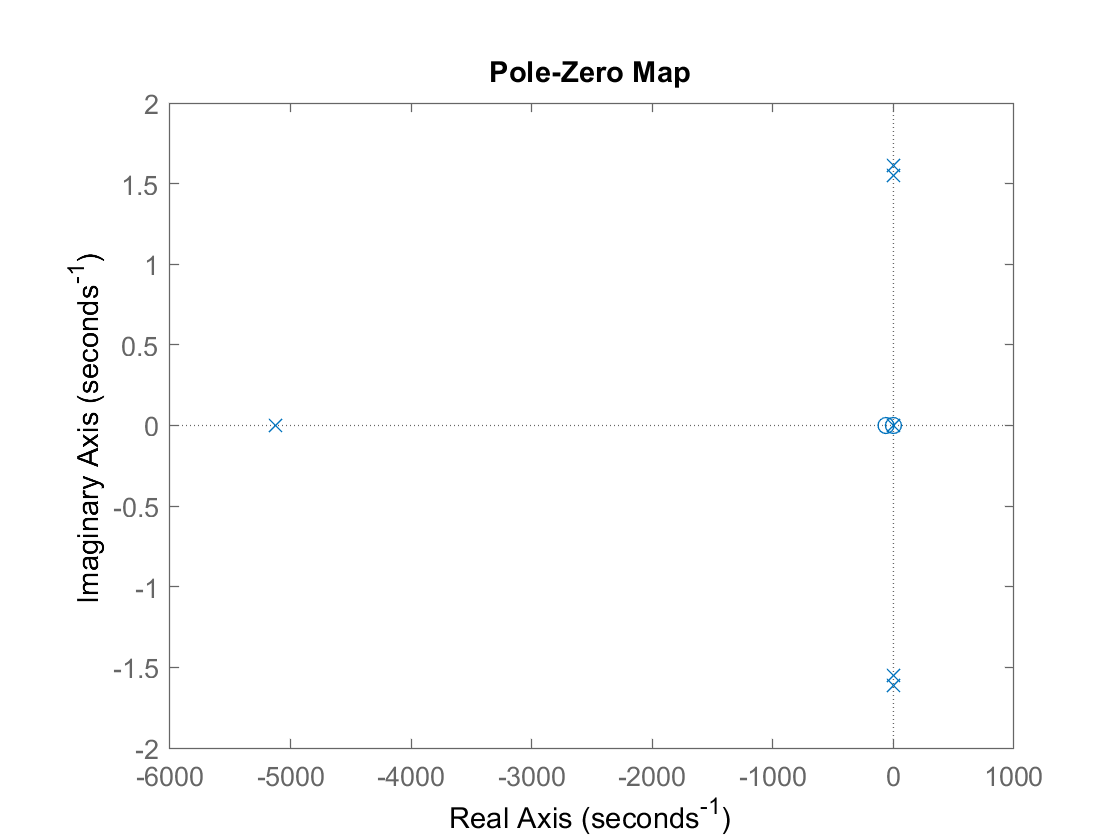

figure
pzmap(fb)

u= zeros(1,10000);
t = [0:1:9999]./100

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u(1:1000)= 1

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


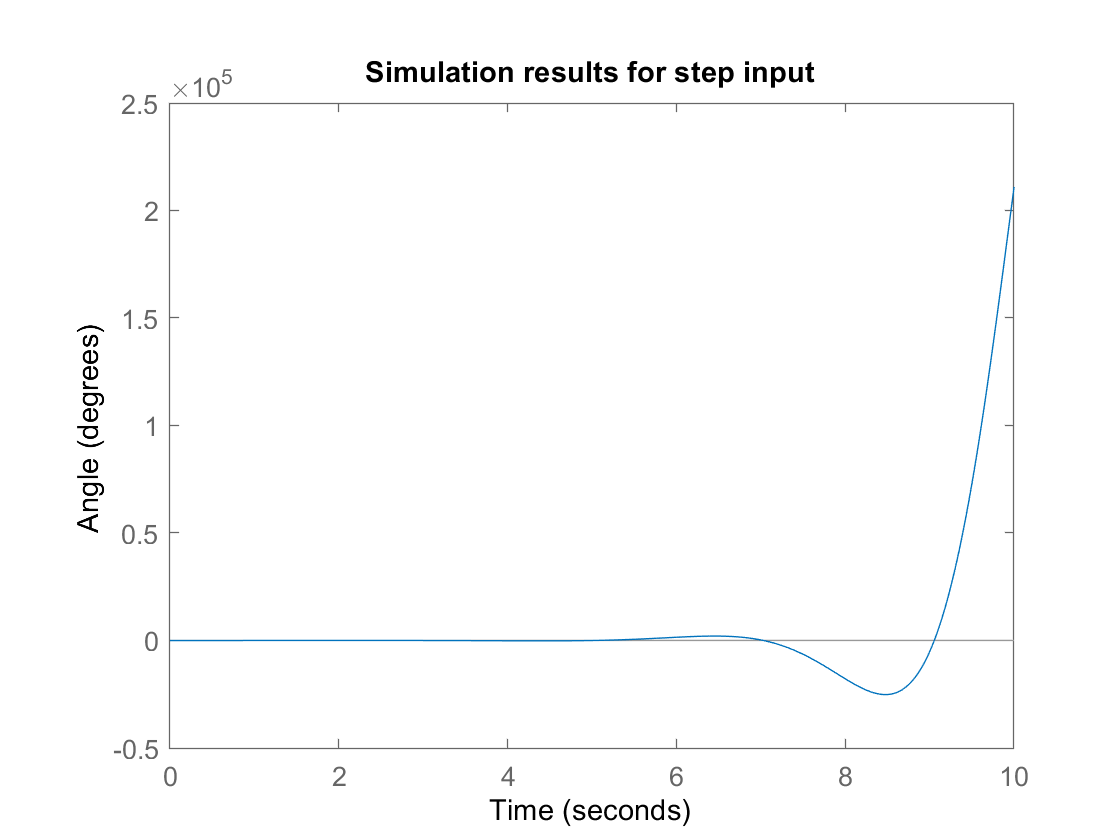

lsim(fb,u,t)
xlim([0,10])
ylabel('Angle (degrees)')
title('Simulation results for step input')